I =imread('Capture33.PNG');
[R,C,K]=size(I);
I=rgb2gray(I)

I = 139×137 uint8 matrix
   133   124   130   131   128   131   132   132   132   130   133   141   139   132   127   130   126   128   146   162   160   160   158   166   166   166   167   167   166   166   167   163   159   164   167   169   166   157   150   143   141   147   138   126   123   118   113   126   136   123
    60    34    48    61    45    48    53    53    53    48    64    85    82    58    45    55    43    49   107   157   153   153   148   169   172   172   172   170   167   167   171   163   153   160   166   172   164   143   117    92    96   116   127   117   106   105   104   101    83    88
    57    33    34    45    48    54    54    54    45    34    46    73    77    62    48    56    50    43    93   164   161   135   154   175   174   170   172   175   173   171   171   158   126   127   170   176   146   135   115    97   126   123   125   110   110   112   108   104    98    91
    90    72    69    72    68    60    65    65    61    53    61    79

%image=I;
imageArray=I(:);
I=im2double(I)

I =     0.5216    0.4863    0.5098    0.5137    0.5020    0.5137    0.5176    0.5176    0.5176    0.5098    0.5216    0.5529    0.5451    0.5176    0.4980    0.5098    0.4941    0.5020    0.5725    0.6353    0.6275    0.6275    0.6196    0.6510    0.6510    0.6510    0.6549    0.6549    0.6510    0.6510    0.6549    0.6392    0.6235    0.6431    0.6549    0.6627    0.6510    0.6157    0.5882    0.5608    0.5529    0.5765    0.5412    0.4941    0.4824    0.4627    0.4431    0.4941    0.5333    0.4824
    0.2353    0.1333    0.1882    0.2392    0.1765    0.1882    0.2078    0.2078    0.2078    0.1882    0.2510    0.3333    0.3216    0.2275    0.1765    0.2157    0.1686    0.1922    0.4196    0.6157    0.6000    0.6000    0.5804    0.6627    0.6745    0.6745    0.6745    0.6667    0.6549    0.6549    0.6706    0.6392    0.6000    0.6275    0.6510    0.6745    0.6431    0.5608    0.4588    0.3608    0.3765    0.4549    0.4980    0.4588    0.4157    0.4118    0.4078    0.3961    0.3255    0

kernel=ones(3)/9;
meanMatrix=conv2(double(I),kernel,'same');
varianceMatrix = stdfilt(I);
varianceArray=varianceMatrix(:);

[minKValues,Indice] = mink(meanMatrix(:),190)

minKValues =     0.0946
    0.0976
    0.1028
    0.1028
    0.1037
    0.1072
    0.1081
    0.1120
    0.1142
    0.1150


Indice =        16134
       16133
       19000
       19001
       19002
       19003
       18999
       19004
          13
          14


variances=zeros(190,2);
for i=1:190
    variances(i,1)=varianceArray(Indice(i));
    variances(i,2)=Indice(i);
end
k=variances

k = 	1.0e+04 *

    0.0000    1.6134
    0.0000    1.6133
    0.0000    1.9000
    0.0000    1.9001
    0.0000    1.9002
    0.0000    1.9003
    0.0000    1.8999
    0.0000    1.9004
    0.0000    0.0013
    0.0000    0.0014


minVariance=min(variances(:,1))

minVariance = 0.0013

minIndices=[];
for i=1:190
    if(variances(i,1)==minVariance)
        minIndices=[minIndices,variances(i,2)];
    end
end
l=minIndices

l = 2552

iV=[];
for i=1:numel(minIndices)
   iV=[iV,imageArray(minIndices(i))]; 
end
IV=iV

IV = uint8
38

Airlight=min(IV)

Airlight = uint8
38

AirlightIndexes=find(IV==Airlight)

AirlightIndexes = 1

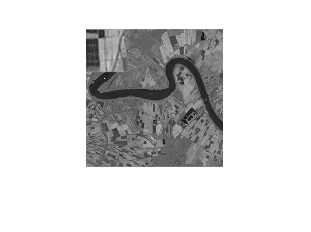

for i=1:numel(AirlightIndexes)
    imageArray(l(AirlightIndexes(i)))=255;
end
B = reshape(imageArray,[R,C]);
imshow(B)